# DeepInterpolation - fMRI Inference Demo

This example imports and uses the DeepInterpolation model in MATLAB for fMRI data (from OpenNeuro). Requires System Identification Toolbox (which can be added with the [Add-On Explorer](https://www.mathworks.com/products/matlab/add-on-explorer.html)).

## Call the setup function to add files to the path

DI_path = setup;

## Download example dataset from OpenNeuro.org

We are using the data published with Horikawa, T. & Kamitani, Y. (2017) Generic decoding of seen and imagined objects using hierarchical visual features. Nature Communications 8:15037. [https://www.nature.com/articles/ncomms15037.](https://www.nature.com/articles/ncomms15037.)

**Tomoyasu Horikawa and Yukiyasu Kamitani (2019). Generic Object Decoding (fMRI on ImageNet). OpenNeuro. [Dataset] doi: 10.18112/openneuro.ds001246.v1.2.1**

dataURL = "https://openneuro.org/crn/datasets/ds001246/snapshots/1.2.1/files/sub-01:ses-perceptionTest01:func:sub-01_ses-perceptionTest01_task-perception_run-01_bold.nii.gz";
datafilename = "sub-01_ses-perceptionTest01_task-perception_run-01_bold.nii.gz";

fullDataFilename = fullfile(DI_path , "sampleData", datafilename);
if ~exist(fullDataFilename,"file")
    disp("Downloading one example dataset from Openneuro.org")
    websave(fullDataFilename, dataURL);
else
    disp("Example Dataset already exists. Skipping download.")
end

Example Dataset already exists. Skipping download.


## Settings

extraNoise = false; %optional: introduce extra bad noise for visualization purposes

## Load dataset

allscans = niftiread(fullDataFilename);
allscans = single(allscans);
dataDimensions = size(allscans);
if extraNoise
    allscans = allscans + (randn(dataDimensions) .* 100); %#ok<UNRCH>
end
timeSteps = dataDimensions(4);

Means and standard deviations for normalization

globalMean = mean(allscans, 'all'); % for normalization
globalStd = std(allscans, [], 'all'); % for normalization

## Generate MATLAB-Version of the DeepInterpolation fMRI-Denoiser Network

DeepInterpolation principle published in: Lecoq, J., Oliver, M., Siegle, J.H. *et al.* Removing independent noise in systems neuroscience data using DeepInterpolation. *Nat Methods* **18**, 1401–1408 (2021). https://doi.org/10.1038/s41592-021-01285-2

Original Python Repository: [AllenInstitute/deepinterpolation (github.com)](https://github.com/AllenInstitute/deepinterpolation)

DeepInterpolation-MATLAB Repository: [MATLAB-Community-Toolboxes-at-INCF/DeepInterpolation-MATLAB: A MATLAB implementation of the DeepInterpolation principle. (github.com)](https://github.com/MATLAB-Community-Toolboxes-at-INCF/DeepInterpolation-MATLAB)

fullModelFilename = fullfile(DI_path , "pretrainedModels", "fmri_pretrained_matlab_compatible.mat");
if ~exist(fullModelFilename, "file")
    pretrainedNetworkFn = fullfile(DI_path,...
        "pretrainedModels",...
        "2020_08_28_00_25_fmri_unet_denoiser_mean_absolute_error_2020_08_28_00_25_model.h5");
    wo = weboptions('MediaType','application/octet-stream','CharacterEncoding','ISO-8859-1');
    pretrainedURL = "https://www.dropbox.com/sh/ngx5plndmd4jsca/AAAqeFE9Bw6g72Cm9SC4QkMxa/2020_08_28_00_25_fmri_unet_denoiser_mean_absolute_error_2020_08_28_00_25_model.h5?dl=1";
    websave(pretrainedNetworkFn,pretrainedURL,wo);
    disp("Generating MATLAB Compatible pretrained Denoiser Network");
    net = deepinterp.internal.fmriDenoiserNetwork(fullModelFilename, pretrainedNetworkFn);
else
    disp("Loading MATLAB Compatible pretrained Denoiser Network");
    load(fullModelFilename);
end

Loading MATLAB Compatible pretrained Denoiser Network


## (Optional) Explore the dataset

T = 100; % Select scan to observe
 
orthosliceViewer(allscans(:,:,:,T));

## Denoise one scanned volume

T = 100; % Select Scan to denoise
 

Get dimension of data and find how many 7x steps we can take. We only use full subvolumes

x = dataDimensions(1);
y = dataDimensions(2);
z = dataDimensions(3);
t = dataDimensions(4);
steps = (x-6) * (y-6) * (z-6);

Set some part of the subvolume to zero

nulledVolume = zeros(7, 7, 7, 'single');

Normalize the data

allscans = (allscans - globalMean) / globalStd;

We preallocate the output volume with zeros, which also sets the volume borders equal to zero

denoisedVolume = zeros(x, y, z, 'single');

We now do the inference in nested loops (which is easier to understand)

count = 1;
totalEstimate = inf;
f = waitbar(0, "Estimated time to finish:" + num2str(totalEstimate));

step = 1;
for iz = 4:step:z-3 %for consistency use centered window also in space
    for ix = 4:step:x-3
        for iy = 4:step:y-3
            rawSubVolume = allscans(ix-3:ix+3, iy-3:iy+3, iz-3:iz+3, T-2:T+2);
            rawSubVolume(:, :, :, 3) = nulledVolume; % set center volume to zeros
            tic;
            denoisedSubVolume = predict(net, rawSubVolume); % takes ~2ms on my laptop
            thistoc(rem(count, 40) + 1) = toc; %#ok<SAGROW>
            denoisedVolume(ix, iy, iz) = denoisedSubVolume(4, 4, 4); %avoid overwriting of denoised voxels, with step=1 extract only the center of the prediction
            count = count + 1; 
            if rem(count, 40) == 0
                totalEstimate = ((steps-count) * mean(thistoc)) / 60; % in min
                if ceil(totalEstimate)>1
                    waitbar(count/steps, f, "Estimated time to finish: " + num2str(ceil(totalEstimate)) + " minutes");
                end
            end
        end
    end
end
delete(f);

Undo the normalization

denoisedVolume = denoisedVolume * globalStd + globalMean;
allscans = allscans * globalStd + globalMean;

## (Optional) Visualize denoised dataset

 
orthosliceViewer(denoisedVolume);

## Compare original and denoised volumes

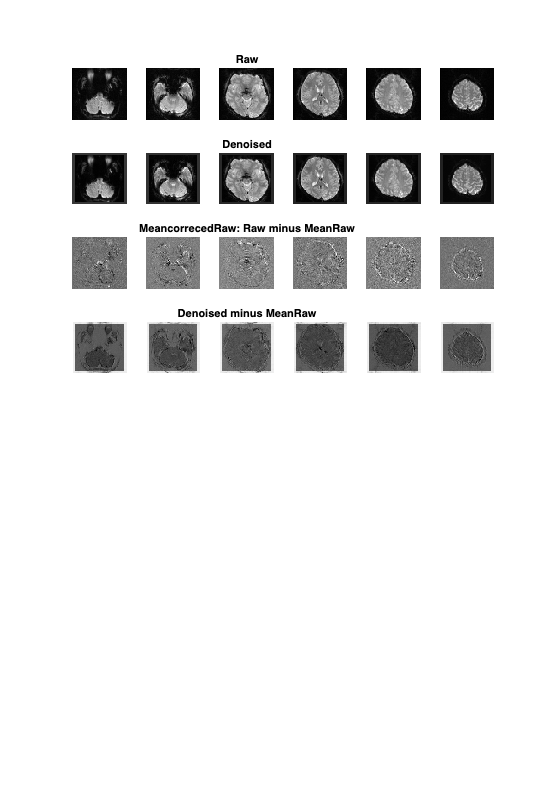

fh = figure();
p = get(fh, 'Position');
set(fh, 'Position', p+[0 -200 0 400]);
clear p
colormap(gray(256));
nSlices = 6;
zvals = round(linspace(10, z-9, nSlices));
meanRawVolume = mean(allscans, 4);
nsub = 8;
for iplot = 1:nSlices
    vz = zvals(iplot);
    showtitle = iplot == 3;
    meancorrectedRawVolume = allscans(:, :, vz, T) - meanRawVolume(:, :, vz);

    subplot(nsub, nSlices, iplot); imagesc(allscans(:, :, vz, T)');
    if showtitle, title('Raw'); end
    axis off
    subplot(nsub, nSlices, iplot+nSlices); imagesc(denoisedVolume(:, :, vz)');
    if showtitle, title('Denoised'); end
    axis off
    subplot(nsub, nSlices, iplot+2*nSlices); imagesc(meancorrectedRawVolume');
    if showtitle, title('MeancorrecedRaw: Raw minus MeanRaw'); end
    axis off    
    subplot(nsub, nSlices, iplot+3*nSlices); imagesc((denoisedVolume(:,:,vz)-meanRawVolume(:,:,vz))');
    if showtitle, title('Denoised minus MeanRaw'); end
    axis off
end

Make a copy for another mean correction plot below

denoisedVolumeSingle = denoisedVolume;

## Denoise a complete dataset in parallel

This would take several hours on a normal computer for the full dataset in full resolution!  Here we are only denoising 64 scans and are using a "reduced resolution" in stepping through the volumes. This may not be satisfactory for research but is good enough for our demonstration purposes.

Please note: the parallel for-loop (parfor) will execute serially on MATLAB-Online and on machines without the[Parallel Computing Toolbox](https://de.mathworks.com/products/parallel-computing.html?requestedDomain=) (PCT). If you have many cores and the PCT this code scales very well though.

step = 5; % should be 1, but that takes very long
targetScans = 50:113; % shoul be the complete dataset (3:t-2);

Normalize the data

allscans = (allscans - globalMean) / globalStd;

We are "repackaging" the data needed to denoise one scan (i.e. all data of 5 time-points) into a cell array. This allows more efficient memory use as workers will not get a full copy of all data but only the data needed for the specific parfor iteration (see about sliced variables in parfor loops here: [Sliced Variables - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/parallel-computing/sliced-variable.html))

allscansCell = cell(numel(targetScans), 1);
for thisT = 1:numel(targetScans)
    localTargetFrame = targetScans(thisT);
    allscansCell{thisT} = allscans(:, :, :, localTargetFrame-2:localTargetFrame+2);
end

Do the inference in nested loops

ds = floor((step-1)/2);
ws = -ds:ds;

allDenoisedVolumesCell = cell(size(allscansCell));
parfor thisScan = 1:numel(targetScans)
    localData = allscansCell{thisScan};
    denoisedVolume = zeros(x, y, z, 'single');
    for iz = 4:step:z-3
        for ix = 4:step:x-3
            for iy = 4:step:y-3
                rawSubVolume = localData(ix-3:ix+3, iy-3:iy+3, iz-3:iz+3, :);
                rawSubVolume(:, :, :, 3) = nulledVolume;
                denoisedSubVolume = predict(net, rawSubVolume);
                denoisedVolume(ix+ws, iy+ws, iz+ws) = denoisedSubVolume(4+ws, 4+ws, 4+ws);
            end
        end
    end
    allDenoisedVolumesCell{thisScan} = denoisedVolume;
    disp("finished denoising scan " + num2str(thisScan));
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 10 workers.
finished denoising scan 1
finished denoising scan 9
finished denoising scan 2
finished denoising scan 4
finished denoising scan 8
finished denoising scan 5
finished denoising scan 10
finished denoising scan 3
finished denoising scan 7
finished denoising scan 6
finished denoising scan 13
finished denoising scan 37
finished denoising scan 31
finished denoising scan 16
finished denoising scan 19
finished denoising scan 22
finished denoising scan 25
finished denoising scan 40
finished denoising scan 28
finished denoising scan 34
finished denoising scan 36
finished denoising scan 35
finished denoising scan 21
finished denoising scan 30
finished denoising scan 29
finished denoising scan 12
finished denoising scan 11
finished denoising scan 20
finished denoising scan 24
finished denoising scan 15
finished denoising scan 14
finished denoising scan 18
finished denoising scan 23
finishe

denoisedVolumes = cat(4, allDenoisedVolumesCell{:});

Undo the normalization

allscans = allscans * globalStd + globalMean;
denoisedVolumes = denoisedVolumes * globalStd + globalMean;

## Add another mean correction to the comparison above

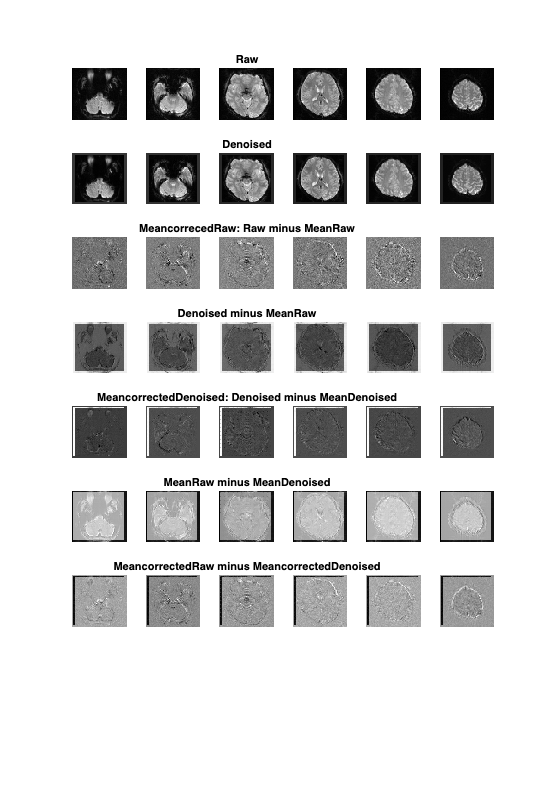

figure(fh);
meanDenoisedVolume = mean(denoisedVolumes, 4);
for iplot = 1:nSlices
    vz = zvals(iplot);
    showtitle = iplot == 3;
    meancorrectedRawVolume = allscans(:, :, vz, T) - meanRawVolume(:, :, vz);
    meancorrectedDenoisedVolume = denoisedVolumeSingle(:, :, vz)-meanDenoisedVolume(:, :, vz);

    subplot(nsub, nSlices, iplot+4*nSlices); imagesc(meancorrectedDenoisedVolume');
    if showtitle, title('MeancorrectedDenoised: Denoised minus MeanDenoised'); end
    axis off
    subplot(nsub, nSlices, iplot+5*nSlices); imagesc((meanRawVolume(:, :, vz)-meanDenoisedVolume(:, :, vz))');
    if showtitle, title('MeanRaw minus MeanDenoised'); end
    axis off
    subplot(nsub, nSlices, iplot+6*nSlices); imagesc((meancorrectedRawVolume-meancorrectedDenoisedVolume)');
    if showtitle, title('MeancorrectedRaw minus MeancorrectedDenoised'); end
    axis off        
end

## Observe the effect of denoising along the time dimension (BOLD response)

We will look at the grey-values of an arbitrary voxel (29,29,20) along the time dimension and compare raw vs. denoised signals

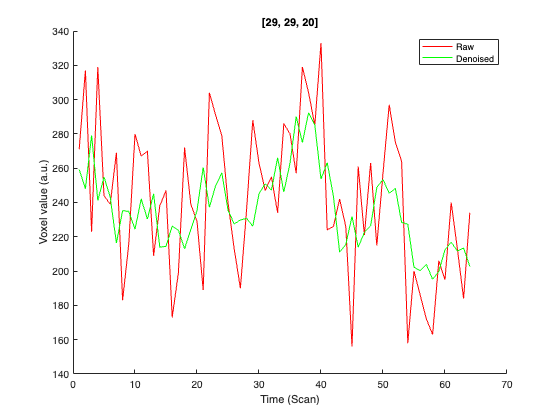

rawVolumes = allscans(:, :, :, targetScans);

pos = [29, 29, 20];
figure();
hold on;
plot(squeeze(rawVolumes(pos(1), pos(2), pos(3), :)), 'r');
plot(squeeze(denoisedVolumes(pos(1), pos(2), pos(3),:)), 'g');
xlabel("Time (Scan)");
ylabel("Voxel value (a.u.)");
legend("Raw", "Denoised");
title(sprintf('[%d, %d, %d]', pos));

Other positions

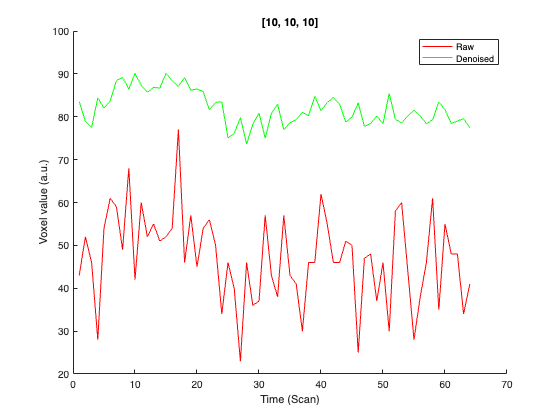

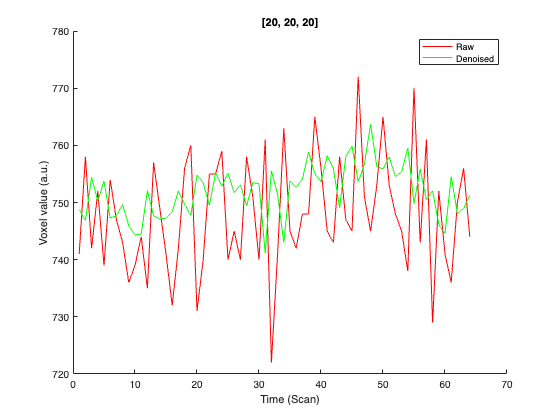

pos = [10, 10, 10; 20, 20, 20];
for j = 1:size(pos, 1)

    figure();
    hold on;
    plot(squeeze(rawVolumes(pos(j, 1), pos(j, 2), pos(j, 3), :)), 'r');
    plot(squeeze(denoisedVolumes(pos(j, 1), pos(j, 2), pos(j, 3),:)), 'g');
    xlabel("Time (Scan)");
    ylabel("Voxel value (a.u.)");
    legend("Raw", "Denoised");
    title(sprintf('[%d, %d, %d]', pos(j, :)));
end